## step 50 [deg] simulations for nominal tracking with lqr e Bryson


% simulate value with step 50 [deg] nominal lqr Bryson

step_amplitude = 50;

data = sim("lab3__lqr__Bryson_sim.slx");

t = data.ScopeData1.time;
tetha_h = data.ScopeData1.signals(1).values;  
tetha_d = data.ScopeData1.signals(2).values;
ref_signal = data.ScopeData1.signals(3).values;
% error = data.ScopeData1.signals(3).values;
command_u =  data.ScopeData1.signals(4).values;

save("lab3__lqr__Bryson_sim.mat",'t','tetha_h','tetha_d','ref_signal');



## Stampa grafico generale

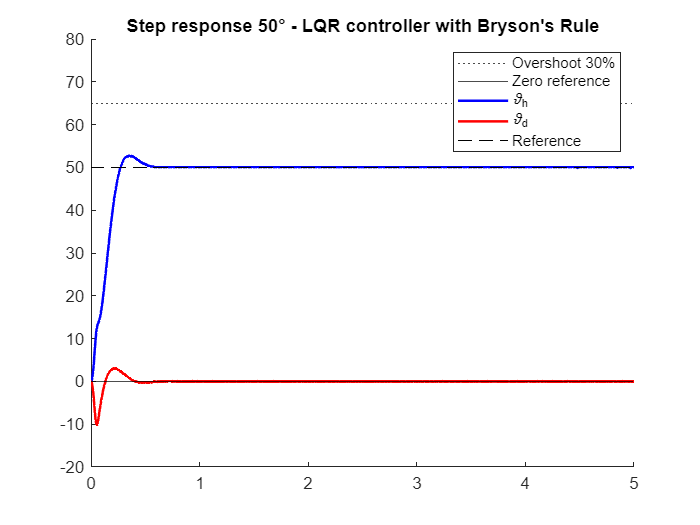


% grafico step 50 deg

load("lab3__lqr__Bryson_sim.mat");
figure;
% plot(t,ref,'k--');
yline(65, 'k:','LineWidth', 0.5, 'DisplayName', 'Overshoot 30%');
yline(0, 'k','LineWidth', 0.5, 'DisplayName', 'Zero reference');
hold on 
plot(t,tetha_h,'b','LineWidth', 1.5, 'DisplayName', '\vartheta_h');
plot(t,tetha_d,'r','LineWidth', 1.5, 'DisplayName', '\vartheta_d');
plot(t,ref_signal,'k--','LineWidth', 0.5, 'DisplayName', 'Reference');
axis([0 5 -20 80])
title('Step response 50° - LQR controller with Bryson''s Rule')
legend
hold off

#### Step response parameters


step_50_wind_up_nominal_lqr = stepinfo(tetha_h, t, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr);

         RiseTime: 0.2010
    TransientTime: 0.3919
     SettlingTime: 0.3919
      SettlingMin: 45.1800
      SettlingMax: 52.7400
        Overshoot: 5.4800
       Undershoot: 0
             Peak: 52.7400
         PeakTime: 0.3420



## grafico step 50 deg per verificare tetha_h - 50 < 0.3 * 50

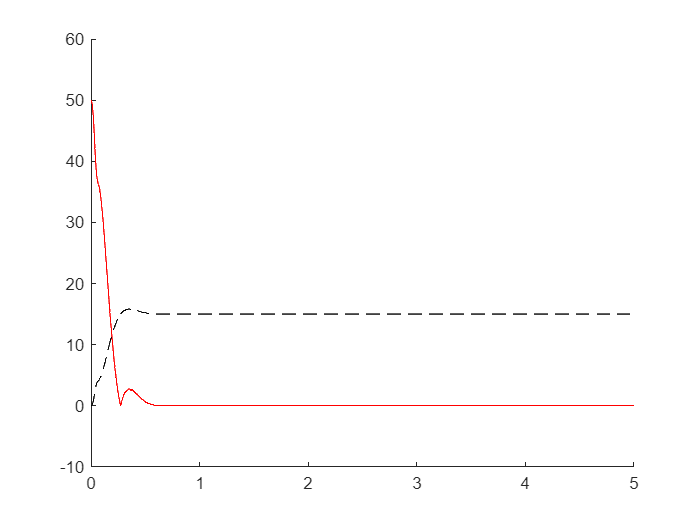


figure;
hold on 
plot(t,abs(tetha_h-50),'r');
plot(t,tetha_h*0.3,'k--');
axis([0 5 -10 60])
hold off

#### grafico step 50 deg per verificare tetha_d < pi/36

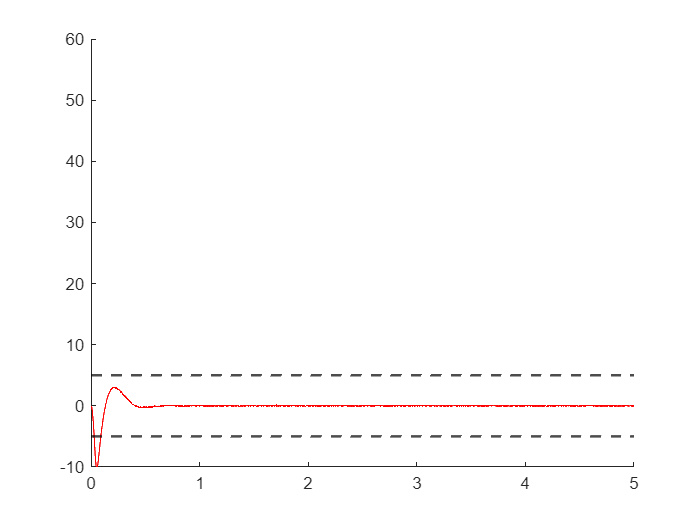


figure;
hold on 
plot(t,tetha_d,'r');
yline(5, 'k--', 'LineWidth', 1.5);
yline(-5, 'k--', 'LineWidth', 1.5);
axis([0 5 -10 60])
hold off

## grafico step 50 deg per verificare u < 10

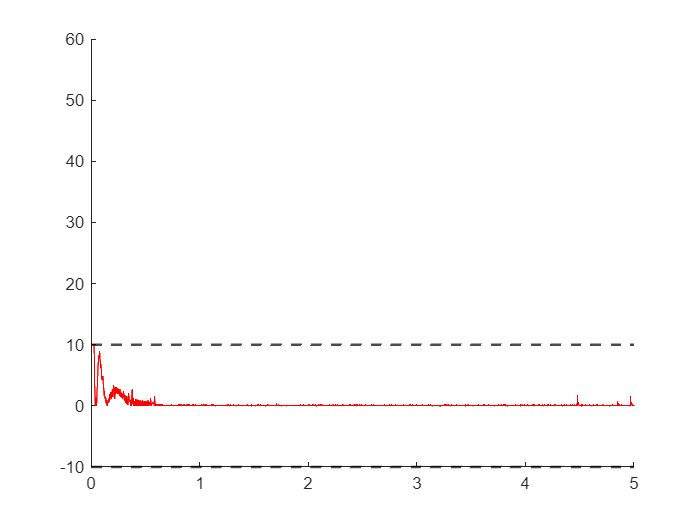



figure;
hold on 
plot(t,abs(command_u),'r');
yline(10, 'k--', 'LineWidth', 1.5);
yline(-10, 'k--', 'LineWidth', 1.5);
axis([0 5 -10 60])
hold off